# **Design Project 3 : Lead-Lag Compensator for a chemical process control System Using MATLAB.**

### Part (a):  Bode Plot Method to find Gain and Phase Margins for Uncompensated system

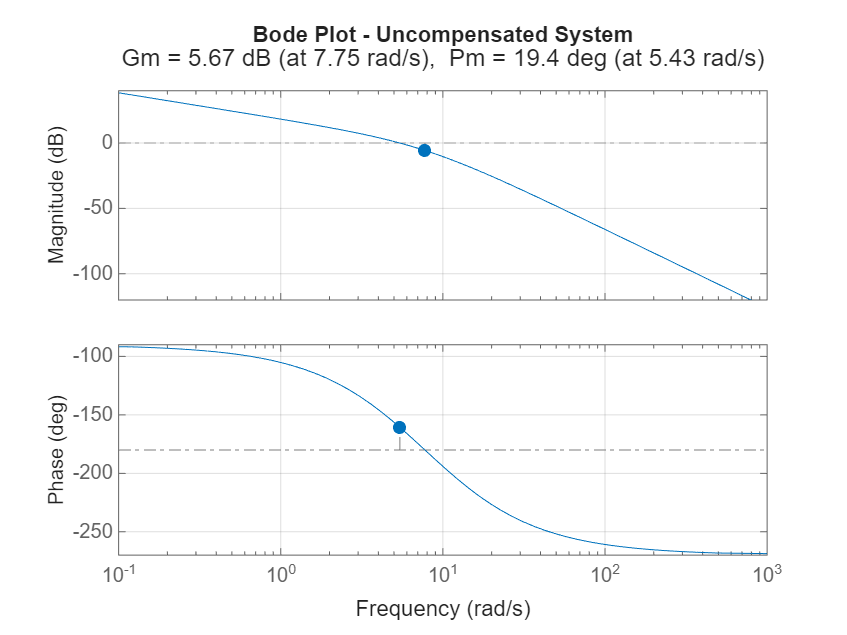

s = tf('s');
G = 500 / (s * (s + 6) * (s + 10));

%___ Bode plot__
figure;
margin(G); % shows Bode Plot with Gain and Phase Margins
grid on;
title('Bode Plot - Uncompensated System');

### Gain and Phase Margins

[GM, PM, w_pc, w_gc] = margin(G);
fprintf('\n--- Uncompensated System Margins ---\n');


--- Uncompensated System Margins ---


fprintf('Gain Margin (dB): %.2f dB\n', 20*log10(GM));

Gain Margin (dB): 5.67 dB


fprintf('Phase Margin: %.2f°\n', PM); % phase margin is less than 20 degrees

Phase Margin: 19.35°


fprintf('Gain Crossover Frequency: %.2f rad/s\n', w_gc);

Gain Crossover Frequency: 5.43 rad/s


fprintf('Phase Crossover Frequency: %.2f rad/s\n', w_pc);

Phase Crossover Frequency: 7.75 rad/s


Kv = dcgain(s*G);
fprintf('Velcoity Error constant Kv: %.4f\n', Kv)

Velcoity Error constant Kv: 8.3333


### **Step Response**

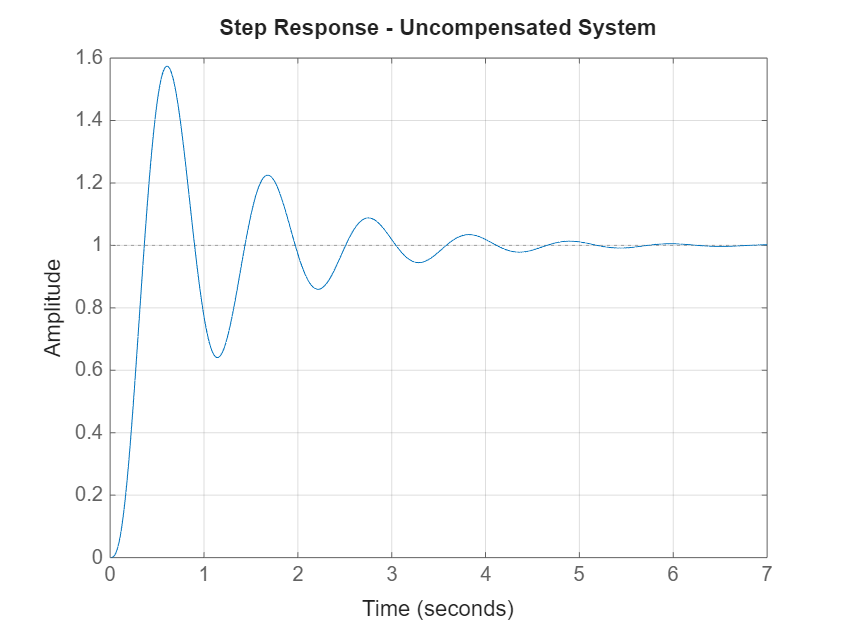

T_uncomp = feedback(G, 1);
figure;
step(T_uncomp);
title('Step Response - Uncompensated System');
grid on;

#### **Ramp Response **

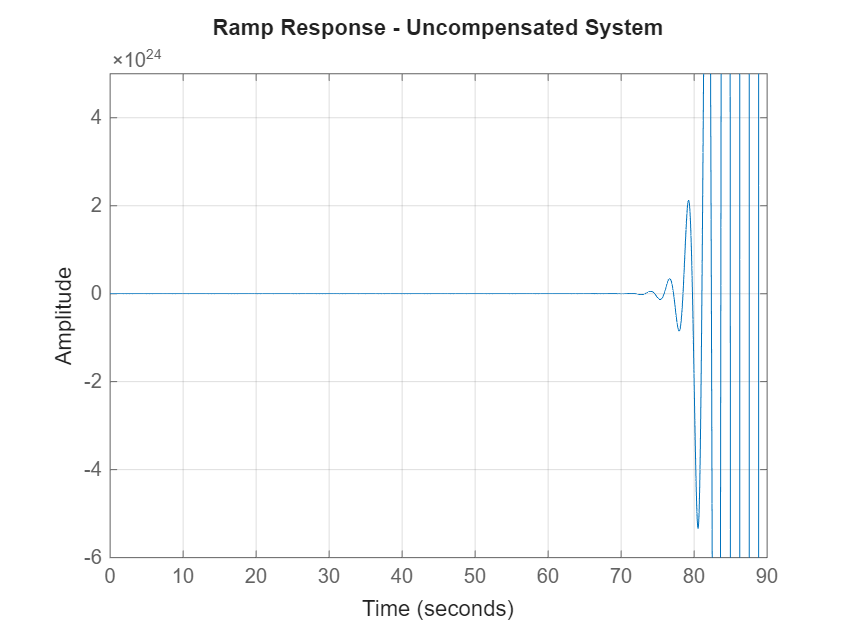

Ramp_uncomp = feedback(G / s, 1);
figure;
step(Ramp_uncomp);
title('Ramp Response - Uncompensated System');
grid on;

## b) Lead - Lag Compensator Design

[GM, PM, w_pc, w_gc] = margin(G);
Kv = dcgain(s * G);  % Original Kv

Desired Phase Margin is >= 50 deg;

Gain Margin >= 10dB; Kv_new = 10*Kv; 

Step 1: Design a lead compensator to increase phase margin, Assuming a desired boost ~30°

Rule of thumb: place zero near desired crossover frequency, and place pole (5–10)× farther right

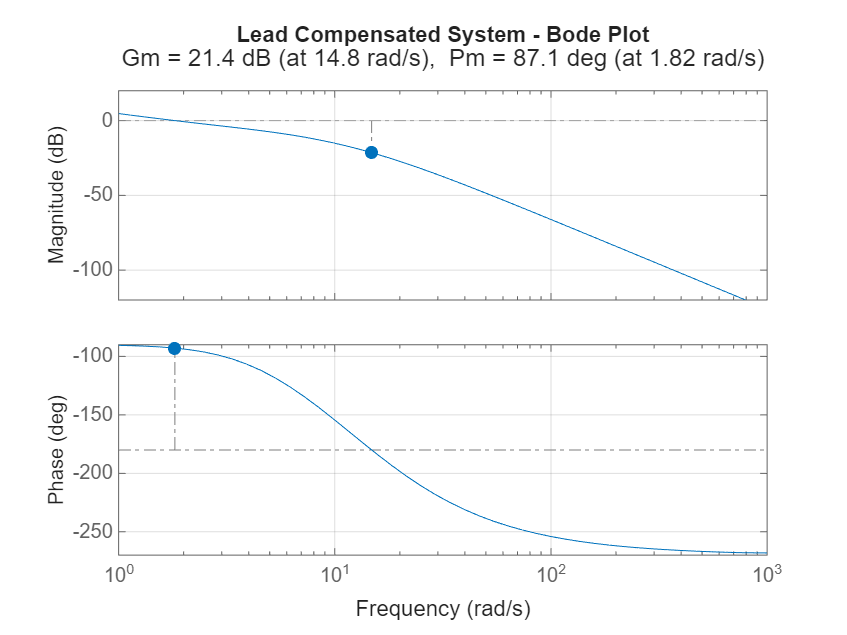

C_lead = (s + 3) / (s + 15);  % Tune these as needed
G_lead = C_lead * G;
figure;
margin(G_lead);
title('Lead Compensated System - Bode Plot');
grid on;

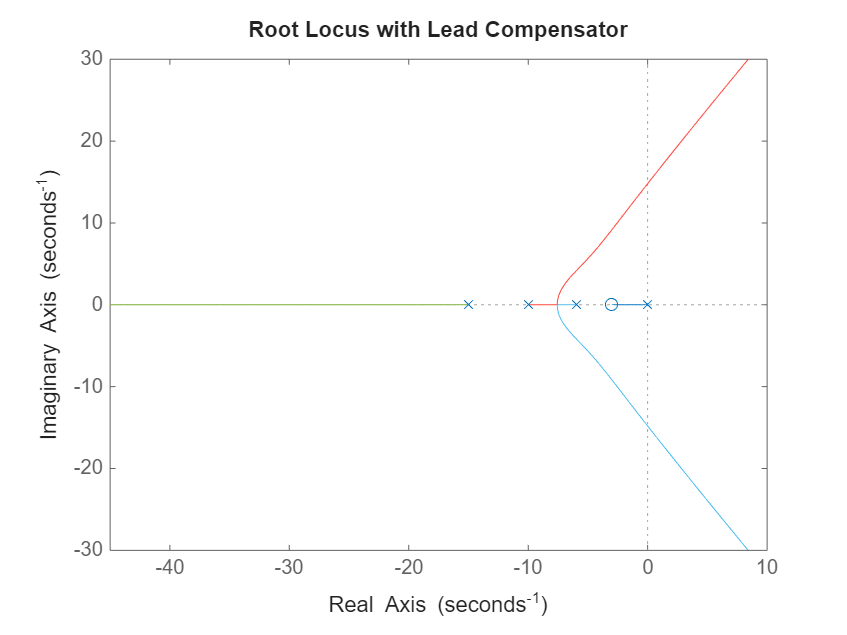

%% Use rlocfind to find appropriate gain
figure;
rlocus(G_lead);
title('Root Locus with Lead Compensator');

Select a point in the graphics window


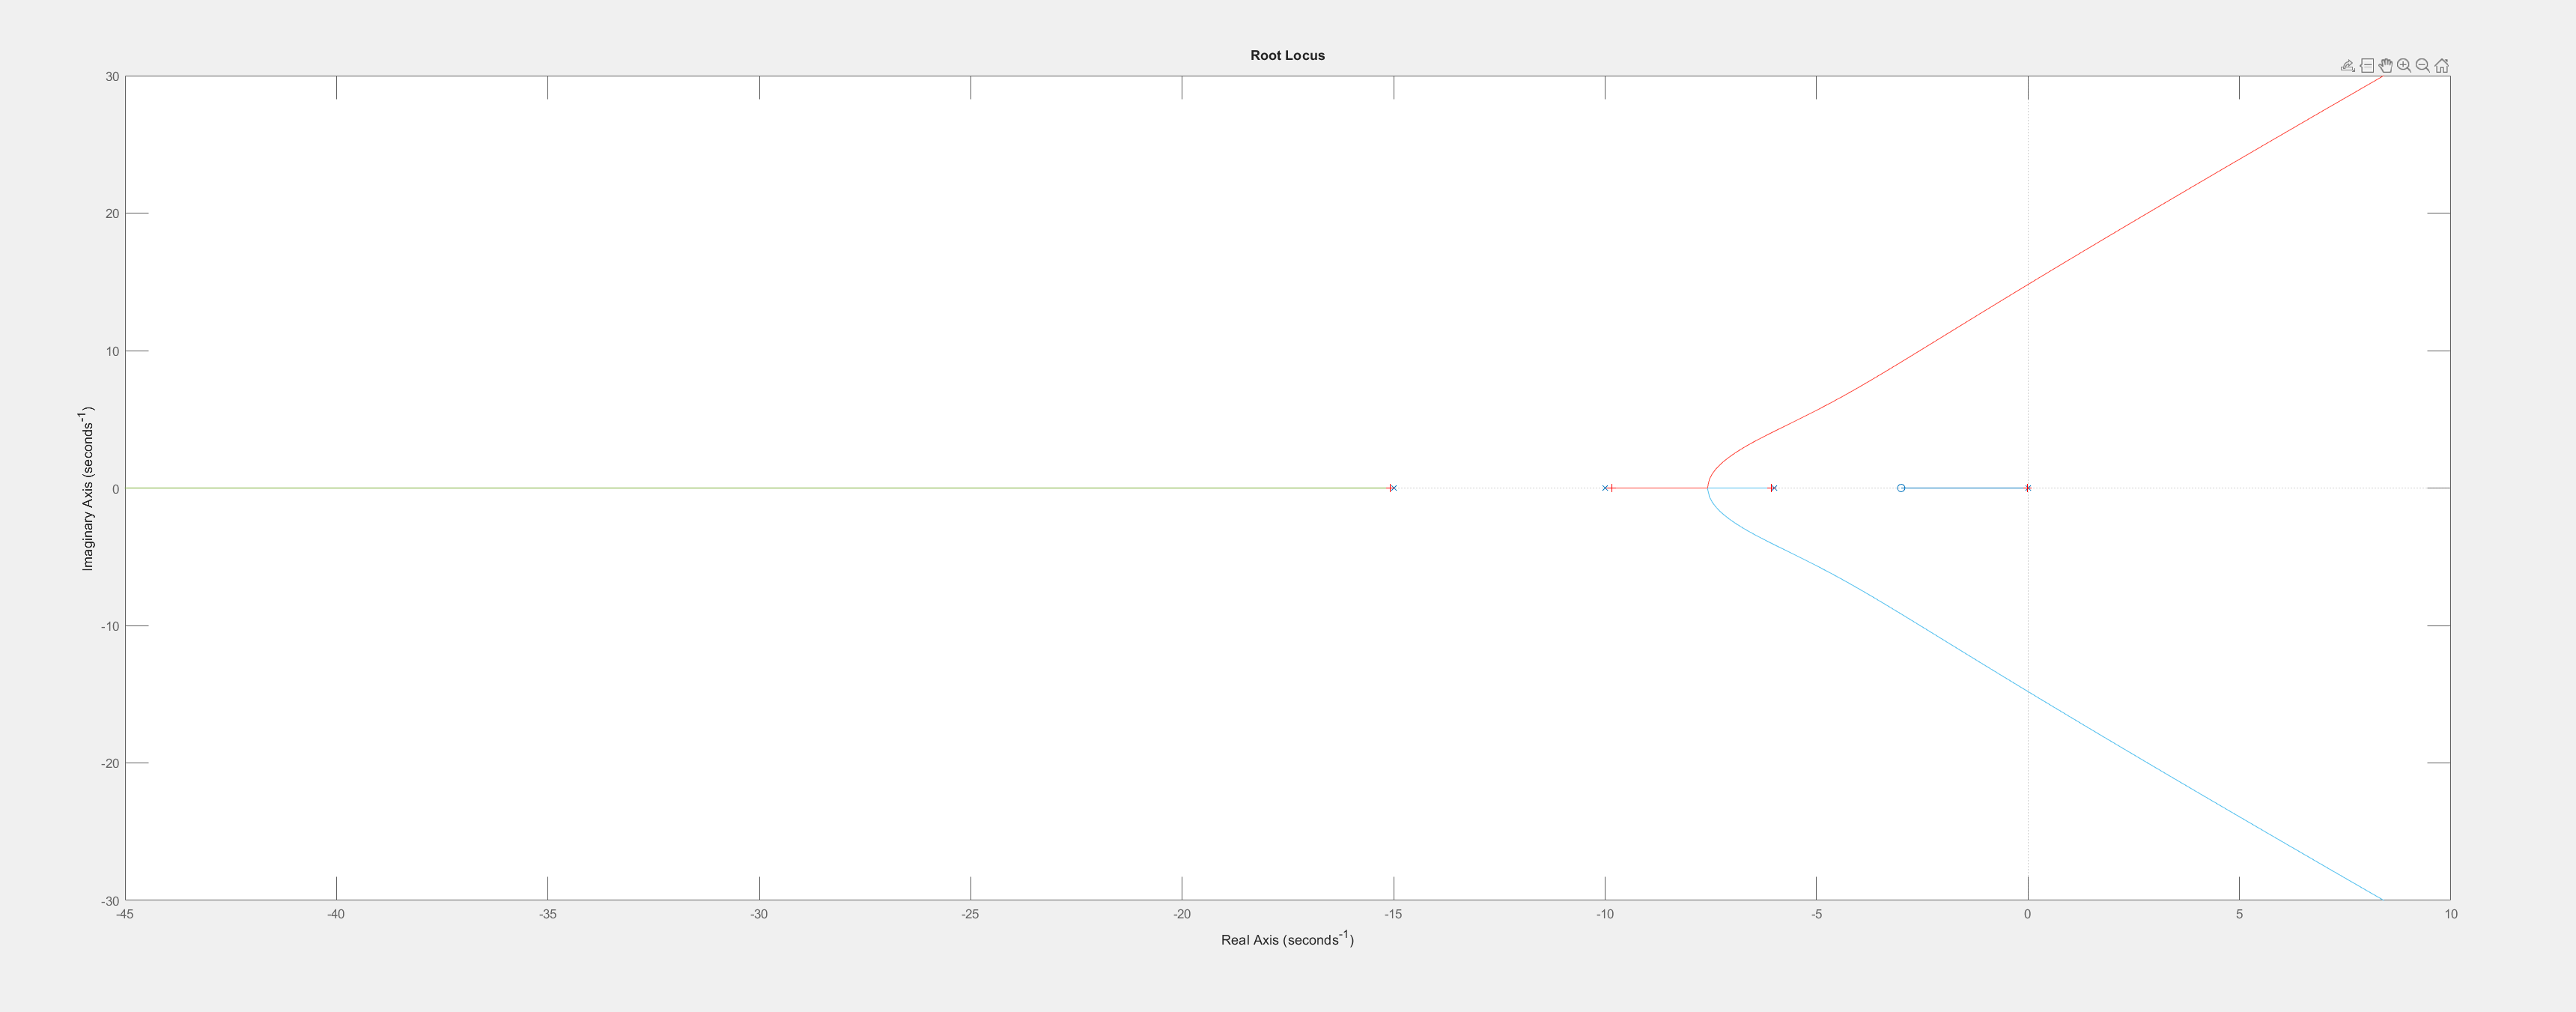

selected_point = -6.0343 - 0.0545i

[K_lead, ~] = rlocfind(G_lead);

%% Applying Lead Compensator and Evaluate
T_lead = feedback(K_lead * G_lead, 1);

#### Lag Compensator

%% Lag Compensator (for Kv improvement)
Kv_orig = dcgain(s * G);
Kv_target = 10 * Kv_orig;
Kv_lead = dcgain(s * (K_lead * G_lead));

alpha = Kv_target / Kv_lead;

% Place zero/pole such that DC gain = alpha (pole closer to origin)
z_lag = 0.1;
p_lag = z_lag / alpha;

C_lag = (s + z_lag) / (s + p_lag);
C_total = K_lead * C_lead * C_lag;
G_comp = C_total * G;
T_comp = feedback(G_comp, 1);

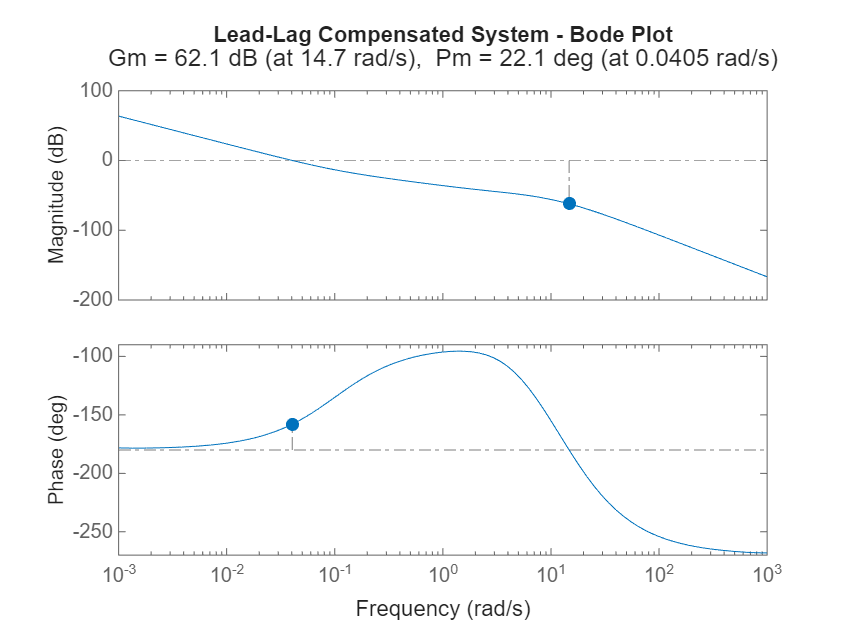

%% Final Bode, Step, Ramp Responses
figure;
margin(G_comp);
title('Lead-Lag Compensated System - Bode Plot');

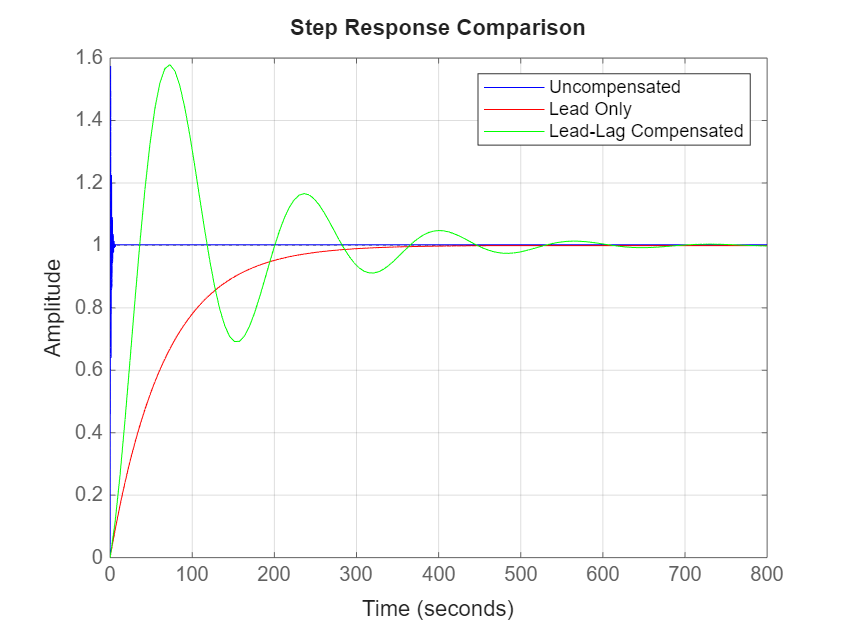


figure;
step(feedback(G,1), 'b', T_lead, 'r', T_comp, 'g');
legend('Uncompensated', 'Lead Only', 'Lead-Lag Compensated');
title('Step Response Comparison');
grid on;

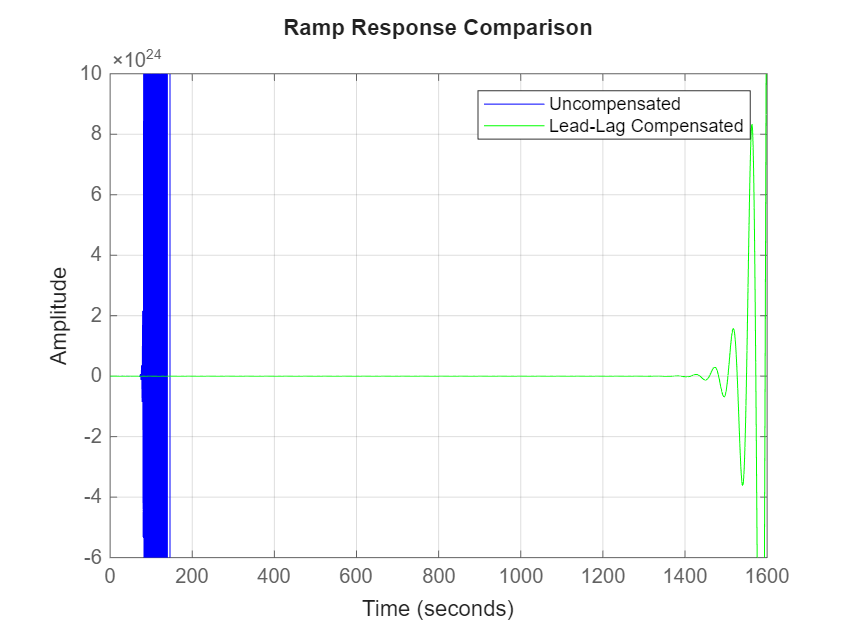


figure;
step(feedback(G/s,1), 'b', feedback(G_comp/s,1), 'g');
legend('Uncompensated', 'Lead-Lag Compensated');
title('Ramp Response Comparison');
grid on;


%% Final Metrics
[GM_final, PM_final, ~, ~] = margin(G_comp);
Kv_final = dcgain(s * G_comp);
S_final = stepinfo(T_comp);

fprintf('\n--- Compensated System Performance ---\n');


--- Compensated System Performance ---


fprintf('Phase Margin: %.2f°\n', PM_final);

Phase Margin: 22.05°


fprintf('Gain Margin: %.2f dB\n', 20*log10(GM_final));

Gain Margin: 62.14 dB


fprintf('Kv (Velocity Error Constant): %.4f\n', Kv_final);

Kv (Velocity Error Constant): 83.3333


fprintf('Rise Time: %.4f sec\n', S_final.RiseTime);

Rise Time: 27.4151 sec


fprintf('Settling Time: %.4f sec\n', S_final.SettlingTime);

Settling Time: 500.8438 sec


fprintf('Overshoot: %.2f%%\n', S_final.Overshoot);

Overshoot: 57.86%
